# **Code for Assignment-3**

## **Importing Sound File and Extracting Input x[n]**

**Parameters**

% Sampling Frequency
Fs = 22050;

% Term in Impulse Response or BandWidth of Low-Pass Filter
k = 1;
Wo = 0.5*Fs;

% Reading Audio File
[Data,Fs] = audioread("msmn1.wav");

% Size of Input Array
s = size(Data);
s = s(1)

s = 110250

% Ns = No.of Samples taken during Fourier Transform
% If x = k*s is not an integer Ns = floor(x) or Ns = ceil(x) is considered such that
% Ns is an Even Integer

x = floor(1*s);     % Considering all points in input audio file to attain maximum output.
x = x(1);
if rem(x,2) == 1
    Ns = x+1;
else
    Ns = x
end

Ns = 110250

**Listening to Audio File**

%soundsc(Data,Fs);

## **Impulse Response h[n] or Low-Pass Filter**

**h_values = h[n]**

**h[n] = h(t) | t=nTs**

Ts = 1/Fs;
n = [-s/2:s/2];
t = (Ts*n)';
h_values = sinc(Wo*t);

**Plotting Impuse Response of System**

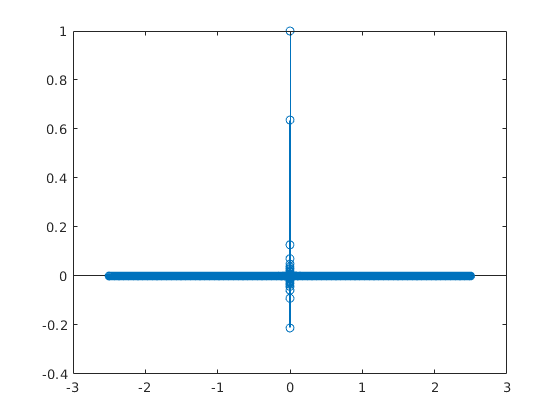

stem(t,h_values)
hold off

**H_w = N-point Fourier Transform of h[n] = H(jw)**

H_w = abs(fft(h_values,Ns));

## **Visualising Fourier Transform of Impulse Response h[n]**

H_w_m_plot = abs(fftshift(H_w));
size(H_w_m_plot);
%t = (s-Ns)/2;
%H_w_plot = padarray(H_w_m_plot,t,'both');
%size(H_w_plot);

**Plotting Fourier Transform of Impuse Response**

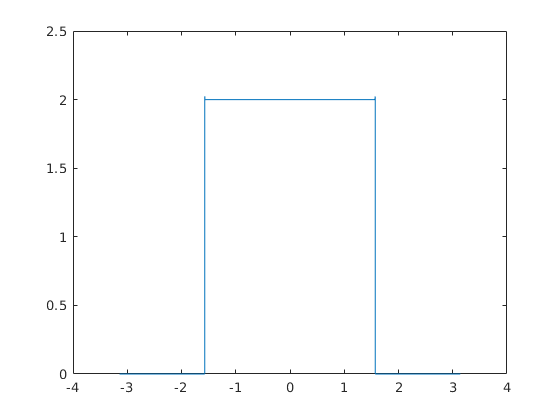

%f = 2*pi*(1*(-s/2:(s/2)-1)/s)';
%size(f);
fm = 2*pi*(1*(-Ns/2:(Ns/2)-1)/Ns)';
plot(fm,H_w_m_plot)
hold off

% plot(f,H_w_plot);

## **Low Frequency Components of x[n]**

**y = y[n] and Data = x[n]**

**Y_w = Y(jw) and X_w = X(jw)**

**Y(jw) = X(jw).H(jw)**

X_w = fft(Data,Ns);
size(X_w)

ans =       110250           1


#### **Output of Signal when passed through Low-Pass Filter**

Y_w = X_w.*H_w;
y = ifft(Y_w);

#### **Listen to High Freqency Components**

%audiowrite('Low_Pass_Audio.wav', y, 22050);
%soundsc(y,Fs);

## **Function to Pass Audio Files through Low-Pass Filter**

**Testing for Different values of Wo**

for w = [0.5*Fs 0.25*Fs 0.125*Fs]
    signal = ProcessLowPassAudio(Data,w,Ns,Fs);
end

filename = 'Low_Pass_Audio_with_W=11025.wav'

filename = 'Low_Pass_Audio_with_W=5512.5.wav'

filename = 'Low_Pass_Audio_with_W=2756.25.wav'

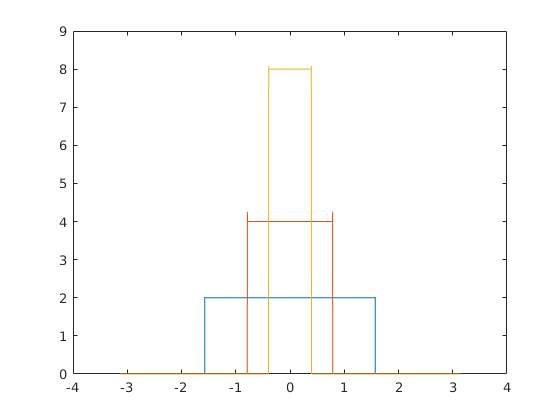

hold off

## **High Pass Filter**

**G_w = N-point Fourier Transform of High-Pass Filter = G(jw)**

`Using Low Pass to High Pass Transformation to get the Transfer Function of High Pass Filter.`

`Note: On using Transformation Low-Pass and High-Pass Filters dont have same Cut-off Frequency.`

**G(jw) = H(j(w+pi))**

% Frequency Response of High-Pass Filter
% fftshift command is used to shift H(jw) by pi
G_w = fftshift(H_w);

**Plotting High-Pass Filter**

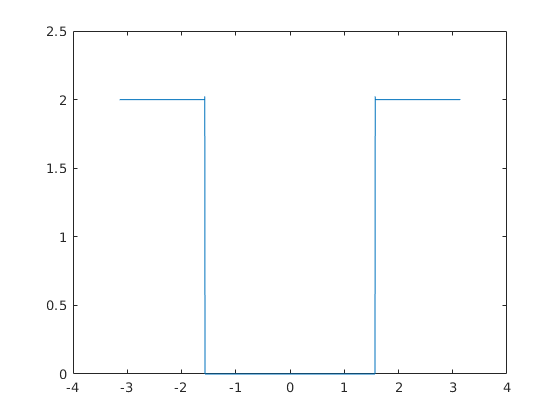

G_w_m_plot = abs(fftshift(G_w));
plot(fm,G_w_m_plot)
hold off

## **High Frequency Components of x[n]**

**z = z[n] and Data = x[n]**

**Z_w = Z(jw) and X_w = X(jw)**

**Z(jw) = X(jw).G(jw)**

**Output of Signal when Passed through High Pass Filter**

Z_w = X_w.*G_w;
z = ifft(Z_w);

**Listen to High Freqency Components**

%soundsc(g,Fs)
%audiowrite('High_Pass_Audio.wav', z, 22050);

## **Function to Pass Audio Files through High-Pass Filter**

**Testing for Different values of Wo**

for w = [0.5*Fs 0.25*Fs 0.125*Fs]
    signal = ProcessHighPassAudio(Data,w,Ns,Fs);
end

filename = 'High_Pass_Audio_with_Cutoff_Freq=5512.5.wav'

filename = 'High_Pass_Audio_with_Cutoff_Freq=8268.75.wav'

filename = 'High_Pass_Audio_with_Cutoff_Freq=9646.875.wav'

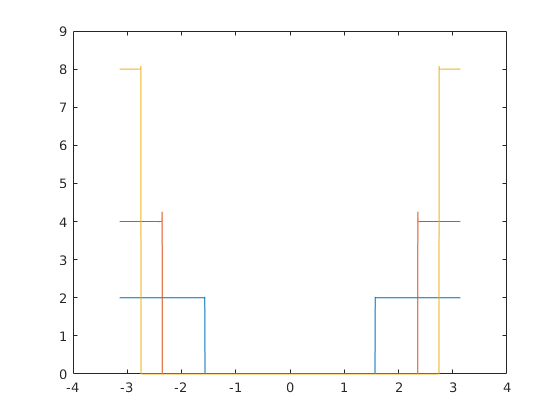

hold off

## **H(z)**

**Parameters**

Fs = 22050;
c = 0.5;
Nz = 1*s;

% a in H(z)
a = 0.9;

% H(z)
Hz = @(z) (1-a)/(1-a*(z^-1));

**Pole and Zero Plot of H(z). By rearranging terms and using a built in function**

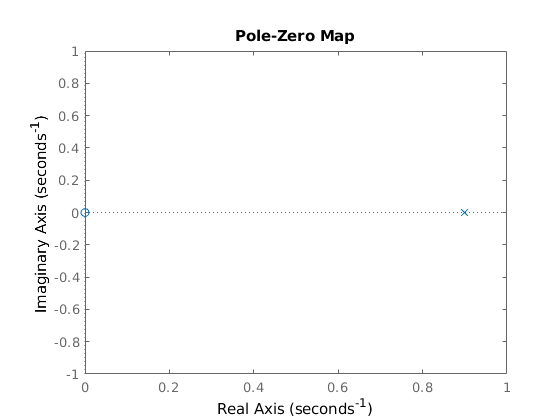

TF = tf([1-a 0],[1 -a]);
pzmap(TF)

**Substituting z = r*e^jw in H(z) where r = 1 which satisfies the condition |z| > |**`a|`

`Hz_w = H(e^jw) --- Low Pass Filter`

`Xz_w = X(jw)`

r = 1;
w = linspace(-pi,pi,Nz);
Hz_w = arrayfun(Hz,(r * exp(1j*w))');
Xz_w = fft(Data,Nz);

**Plotting Low-Pass Filter H(w)**

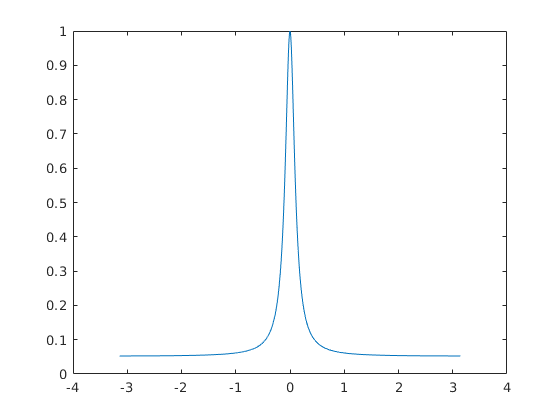

plot(w,Hz_w)

**Output of Signal when Passed through Low Pass Filter**

`Yz_w = Y(jw) = X(jw).H(jw)`

Yz_W = Xz_w.*Hz_w;
yz = real(ifft(Yz_W));

**Listening to Low Frequency Components**

%soundsc(yz,Fs);
audiowrite('H(z)_Low_Pass_Audio.wav', yz, 22050);

`Gz_w = G(e^jw) --- High Pass Filter`

`Using Low Pass to High Pass Transformation to get the Transfer Function of High Pass Filter`

`Note: On using Transformation Low-Pass and High-Pass Filters dont have same Cut-off Frequency.`

**G(jw) = H(j(w+pi))**

Gz_w = fftshift(Hz_w);

**Plotting High Pass Filter G(w)**

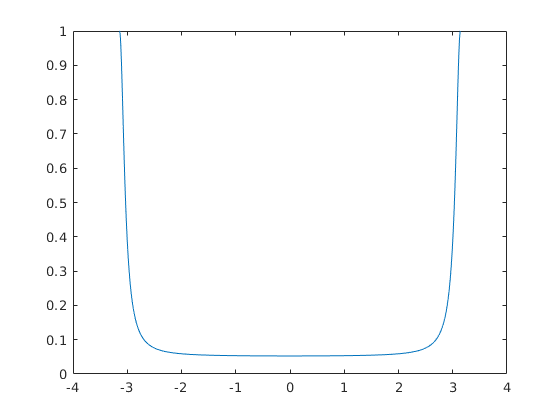

plot(w,Gz_w)

`Zz_w = Z(jw) = X(jw).G(jw)`

**Output of Signal when Passed through High Pass Filter**

Zz_w = Xz_w.*Gz_w;
zz = real(ifft(Zz_w));

**Listening to High Frequency Components**

%soundsc(zz,Fs);
audiowrite('H(z)_High_Pass_Audio.wav', zz, 22050);

## **Functions used in the Code**

function signal = ProcessLowPassAudio(data,w,m,Fs)
    % t = nTs substitution
    Ts = 1/Fs;
    n = [-m/2:m/2];
    t = (Ts*n)';
    
    % Impulse Response of Low-Pass Filter
    h_values = sinc(w*t);
    
    % Fourier Transform of Impulse Response
    H_w = abs(fft(h_values,m));
    
    % Fourier Transform of Input
    X_w = fft(data,m);
    
    % Multiplication in Frequency Domain
    Y_w = X_w.*H_w;
    
    % Inverse Fourier Transform or Reconstruction of Signal
    signal = ifft(Y_w);
    
    H_w_m_plot = abs(fftshift(H_w));
    fm = 2*pi*(1*(-m/2:(m/2)-1)/m)';
    plot(fm,H_w_m_plot)
    hold on

    a = 'Low_Pass_Audio_with_W=';
    b = num2str(w);
    c = '.wav';
    filename = strcat(a,b,c)
    %soundsc(y,Fs)
    audiowrite(filename, signal, Fs);
end

function signal = ProcessHighPassAudio(data,w,m,Fs)
    % t = nTs substitution
    Ts = 1/Fs;
    n = [-m/2:m/2];
    t = (Ts*n)';
    
    % Impulse Response of Low-Pass Filter
    h_values = sinc(w*t);
    
    % Fourier Transform of Impulse Response
    H_w = abs(fft(h_values,m));
    
    % Fourier Transform of Input
    X_w = fft(data,m);
    
    % Low-Pass to High Pass Transformation and Multiplication in Frequency Domain
    G_w = fftshift(H_w);            
    Z_w = X_w.*G_w;
    
    % Inverse Fourier Transform or Reconstruction of Signal
    signal = ifft(Z_w);
    
    G_w_m_plot = abs(fftshift(G_w));
    fm = 2*pi*(1*(-m/2:(m/2)-1)/m)';
    plot(fm,G_w_m_plot)
    hold on
    
    a = 'High_Pass_Audio_with_Cutoff_Freq=';
    b = num2str((Fs-w)/2);
    c = '.wav';
    filename = strcat(a,b,c)
    
    %soundsc(y,Fs)
    audiowrite(filename, signal, Fs);
end